# Sistemas de Control - EX1

% Periodo de muestreo del sistema
T_mu = 4.5 

T_mu = 4.5000

% Obtener los valores medidos
m_p = get(out, "m_p");

Unrecognized function or variable 'out'.

To = get(out, "To");
tout = get(out, "tout");
tout = tout(5:end);

figure(1)
plot(tout, m_p)
title('Flujo de masa de aire')
xlabel('Tiempo (s)')
ylabel('Flujo de masa (kg/s)')

figure(2)
plot(tout, To)
title('Temperatura del aire a la salida')
xlabel('Tiempo (s)')
ylabel('Temperatura (°C)')

## Para systemIdentification

m_p_r = 0.02; % Punto de operación
To_r = 58.83;

% Considerando desde el punto de operación
m_p_i = m_p(80:end) - m_p_r;
To_i = To(80:end) - To_r;

% Obtenidos con systemIdentification
G = tf(p2z0)


G =
 
  From input "u1" to output "y1":
           -3.487
  -------------------------
  s^2 + 0.1207 s + 0.004541
 
Name: p2z0
Continuous-time transfer function.
Model Properties


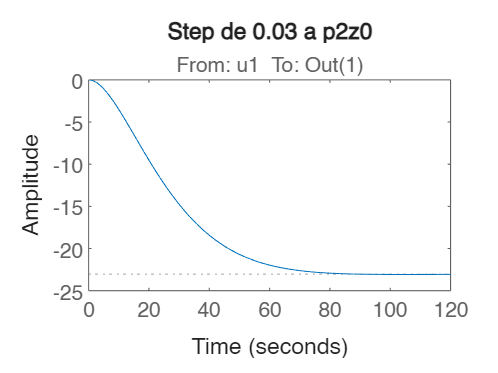

step(0.03*G)
title('Step de 0.03 a p2z0')

G1 = tf(p2z1)


G1 =
 
  From input "u1" to output "y1":
       31.36 s - 6.667
  -------------------------
  s^2 + 0.2003 s + 0.008676
 
Name: p2z1
Continuous-time transfer function.
Model Properties


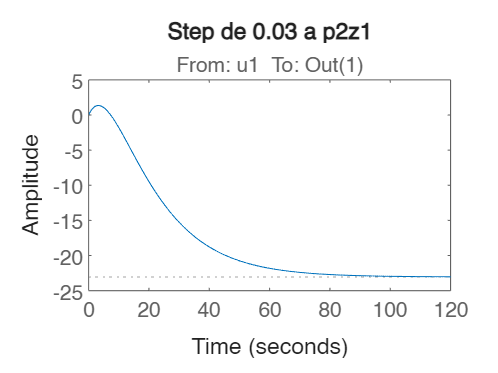

step(0.03*G1)
title('Step de 0.03 a p2z1')

### Diseño del controlador

Tes = 100 

Tes = 100

Mp = 0.05

Mp = 0.0500


% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -0.0400 + 0.0419i

s2 = -sigma-wd*1j

s2 = -0.0400 - 0.0419i


so = -2*sigma

so = -0.0800

### PI

Ti = -1/so

Ti = 12.5000

Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 0.08
  --------
     s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  From input "u1" to output:
        -3.487 s - 0.279
  -----------------------------
  s^3 + 0.1207 s^2 + 0.004541 s
 
Continuous-time transfer function.
Model Properties


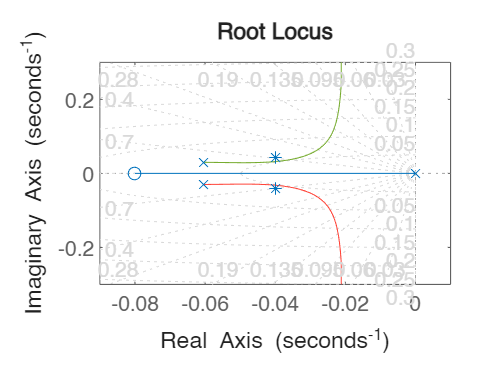

figure(3)
rlocus(-Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
% axis([-0.5 0.2 -0.1  0.1])
hold off

Kp = -0.000349 % PI

Kp = -3.4900e-04

%En lazo cerrado
Glc = feedback(Kp*Gol,1)


Glc =
 
  From input "u1" to output:
           0.001217 s + 9.736e-05
  -----------------------------------------
  s^3 + 0.1207 s^2 + 0.005758 s + 9.736e-05
 
Continuous-time transfer function.
Model Properties


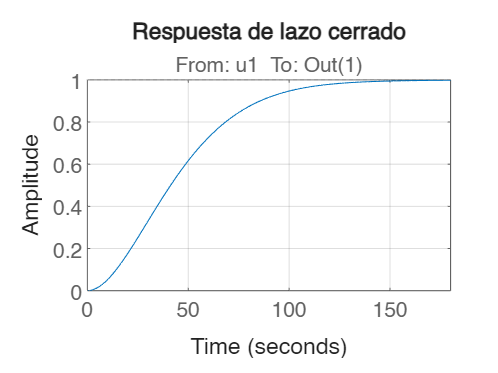


figure(2)
step(Glc);
title('Respuesta de lazo cerrado')
grid on

T_c = 9

T_c = 9

# Servosistema

## Espacio de estados

clear all;
close all;
A = [0 1; -0.004541 -0.1207]

A =          0    1.0000
   -0.0045   -0.1207



B = [0
     1]

B =      0
     1



C = [-3.487 0]

C =    -3.4870         0



Tes = 100

Tes = 100

Mp = 0.05

Mp = 0.0500


% Factor de amortiguamiento relativo
far = -log(Mp)/sqrt(pi^2 + log(Mp)^2)

far = 0.6901


sigma = 4/Tes

sigma = 0.0400

wn = sigma/far

wn = 0.0580

fi = acos(far)

fi = 0.8092

% Tiempo de subida
Tr = exp(fi/tan(fi))/wn

Tr = 37.3211


% Tr = 37.3 

T = 4; % Aprox. Tr/10 

% Muestreo del sistema
FI = eye(2)*T + A*T^2/2 + A^2*T^3/6 + A^3*T^4/24

FI =     3.9574    6.8195
   -0.0310    3.1343


G = eye(2) + A*FI

G =     0.9690    3.1343
   -0.0142    0.5907


H = FI*B

H =     6.8195
    3.1343


### Servosistema

% Servosistema agregando integrador
GN = [G zeros(2, 1)
    -C*G 1]

GN =     0.9690    3.1343         0
   -0.0142    0.5907         0
    3.3790   10.9293    1.0000


HN = [H
    -C*H]

HN =     6.8195
    3.1343
   23.7796


% Controlabilidad
CoN = [HN GN*HN GN^2*HN]

CoN =     6.8195   16.4321   21.4222
    3.1343    1.7544    0.8025
   23.7796   81.0784  155.7776


det_CoN = det(CoN)

det_CoN = -1.7392e+03

% Dinámica deseada
wd = -pi*sigma/log(Mp)

wd = 0.0419

s1 = -sigma + wd*1i

s1 = -0.0400 + 0.0419i

s2 = -sigma - wd*1i

s2 = -0.0400 - 0.0419i

s3 = -2*sigma

s3 = -0.0800


% Polos discretos
z1 = exp(T*s1)

z1 = 0.8402 + 0.1423i

z2 = exp(T*s2)

z2 = 0.8402 - 0.1423i

z3 = exp(T*s3)

z3 = 0.7261


% Diseño
KN = acker(GN, HN, [z1 z2 z3])

KN =     0.0045    0.0369    0.0003


K2 = KN(1:2)

K2 =     0.0045    0.0369


K1 = -KN(3)

K1 = -2.8511e-04

### Observador

% Observabilidad
Ob = [C
      C*G]

Ob =    -3.4870         0
   -3.3790  -10.9293


detOb = det(Ob) % detOb = -284.54 != 0 -> Observable

detOb = 38.1104


% Polos del observador
so1 = 2*s1;
so2 = 2*s2;

zo1 = exp(T*so1)

zo1 = 0.6856 + 0.2391i

zo2 = exp(T*so2)

zo2 = 0.6856 - 0.2391i


% Obs en tiempo discreto
Ke = acker(G', C', [zo1 zo2])'

Ke =    -0.0540
   -0.0020
